clc; clear; close all;

pro600 = importrobot("pro600.urdf");
pro600.DataFormat = 'column';
q_home = [8.63 -130.20 -128.53 -11.27 90.00 1.38]'*pi/180;
eeName = 'link6';
T_home = getTransform(pro600, q_home, eeName);
T_home(1:4,4) =  [0;0;0;1];

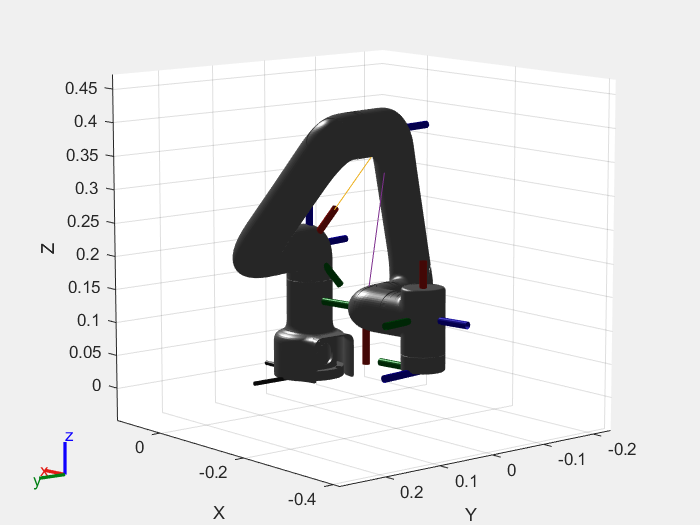

show(pro600,q_home);
axis auto;
view([230,10]); 

% waypoints setting
toolPositionHome = [0.4550    0.0010    0.4340];

[Y, X] = csvimport('waypoints.csv', 'columns', {'Row', 'Column'});

[x, y] = mapper(X, Y);

z = 0.0692 * ones(size(x));

waypoints = double([x y z]'); %3x14
% waypoints = double([-0.3310 0.0601 0.0692; x1 y1 z; x2 y2 z; x3 y3 z; x4 y4 z; x5 y5 z; x6 y6 z; x7 y7 z; x8 y8 z;]'); %3x9

orientations = ([0 -pi/2 pi]' .* ones(size(waypoints))); %3x9

% waypopint times and velocities

waypointTimes = 0:2:(2 * (numel(x)-1));
ts = 0.25;
trajTimes = 0:ts:waypointTimes(end);

waypointVels = 0.1 *[ 0  1  0;
                     -1  0  0;
                      0 -1  0;
                      1  0  0;
                      0	 1  0]';

waypointAccels = zeros(size(waypointVels));
waypointAccelTimes = diff(waypointTimes)/4;

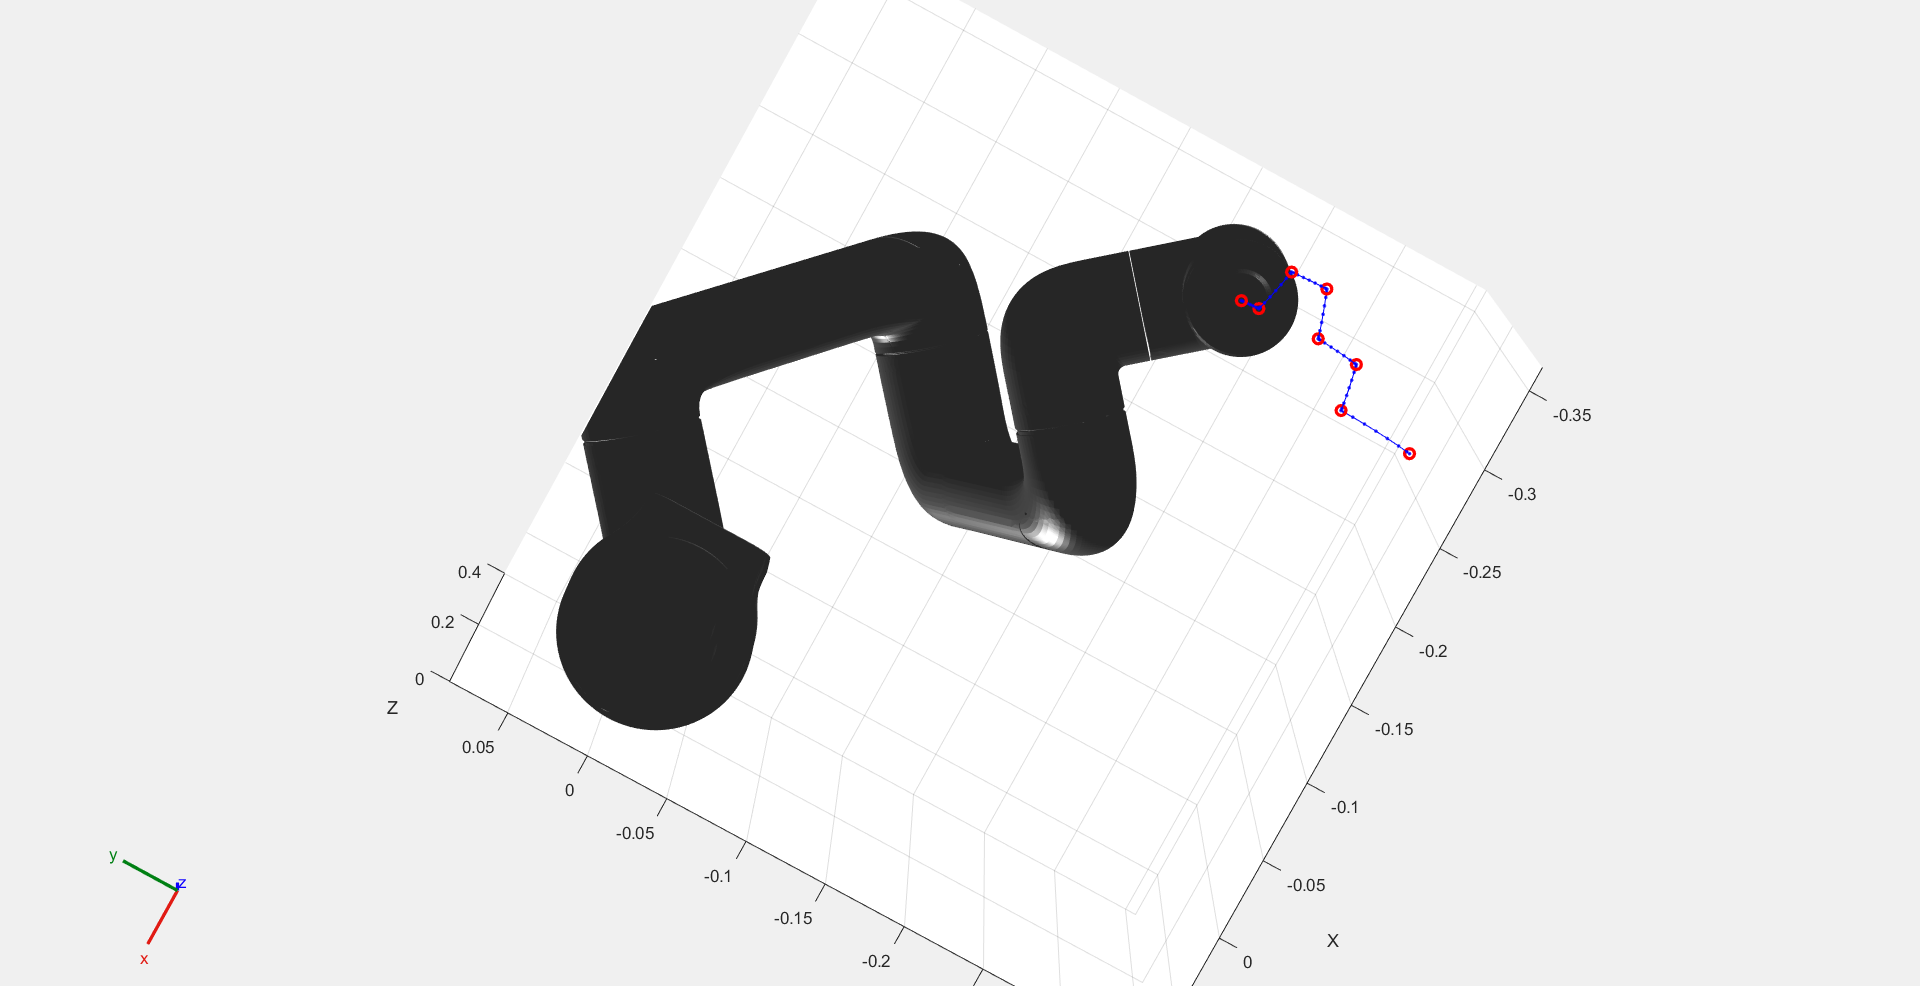

% Inverse kinamatics

ik = inverseKinematics('RigidBodyTree',pro600);
ikWeights = [1 1 1 1 1 1];
ikInitGuess = q_home';
ikInitGuess(ikInitGuess > pi) = ikInitGuess(ikInitGuess > pi) - 2*pi;
ikInitGuess(ikInitGuess < -pi) = ikInitGuess(ikInitGuess < -pi) + 2*pi;

plotMode = 1; % 0 = None, 1 = Trajectory, 2 = Coordinate Frames
show(pro600,q_home,'Frames','off','PreservePlot',false);
hold on
if plotMode == 1
    hTraj = plot3(waypoints(1,1),waypoints(2,1),waypoints(3,1),'b.-');
end
plot3(waypoints(1,:),waypoints(2,:),waypoints(3,:),'ro','LineWidth',2);
axis auto;
view([230,10]);

includeOrientation = true; 
numWaypoints = size(waypoints,2);
numJoints = numel(pro600.homeConfiguration);
jointWaypoints = zeros(numJoints,numWaypoints);
for idx = 1:numWaypoints
    if includeOrientation
        tgtPose = trvec2tform(waypoints(:,idx)') * eul2tform(orientations(:,idx)');
    else
        tgtPose = trvec2tform(waypoints(:,idx)') * eul2tform([pi/2 0 pi/2]); %#ok<UNRCH> 
    end
    [config,info] = ik(eeName,tgtPose,ikWeights',ikInitGuess');
    jointWaypoints(:,idx) = config';
end

trajType = 'trap';
switch trajType
    case 'trap'
        [q,qd,qdd] = trapveltraj(jointWaypoints,numel(trajTimes), ...
            'AccelTime',repmat(waypointAccelTimes,[numJoints 1]), ... 
            'EndTime',repmat(diff(waypointTimes),[numJoints 1]));
                            
    case 'cubic'
        [q,qd,qdd] = cubicpolytraj(jointWaypoints,waypointTimes,trajTimes, ... 
            'VelocityBoundaryCondition',zeros(numJoints,numWaypoints));
        
    case 'quintic'
        [q,qd,qdd] = quinticpolytraj(jointWaypoints,waypointTimes,trajTimes, ... 
            'VelocityBoundaryCondition',zeros(numJoints,numWaypoints), ...
            'AccelerationBoundaryCondition',zeros(numJoints,numWaypoints));
        
    case 'bspline'
        ctrlpoints = jointWaypoints; % Can adapt this as needed
        [q,qd,qdd] = bsplinepolytraj(ctrlpoints,waypointTimes([1 end]),trajTimes);
        % Remove the first velocity sample
        qd(:,1) = zeros (7,1);    
    otherwise
        error('Invalid trajectory type! Use ''trap'', ''cubic'', ''quintic'', or ''bspline''');
end

for idx = 1:numel(trajTimes)  
 
    config = q(:,idx)';
    
    % Find Cartesian points for visualization
    eeTform = getTransform(pro600,config',eeName);
    if plotMode == 1
        eePos = tform2trvec(eeTform);
        set(hTraj,'xdata',[hTraj.XData eePos(1)], ...
                  'ydata',[hTraj.YData eePos(2)], ...
                  'zdata',[hTraj.ZData eePos(3)]);
    elseif plotMode == 2
        plotTransforms(tform2trvec(eeTform),tform2quat(eeTform),'FrameSize',0.05);
    end
 
    % Show the robot
    show(pro600,config','Frames','off','PreservePlot',false);
    title(['Trajectory at t = ' num2str(trajTimes(idx))])
    drawnow   
    
end

% Initialize the inverse kinematics solver
ik = inverseKinematics('RigidBodyTree', pro600);
ikWeights = [1 1 1 1 1 1]; % Weights for the optimization
ikInitGuess = q_home'; % Initial guess for the solver

% Prepare to store joint angles
numWaypoints = size(waypoints, 2);
numJoints = numel(pro600.homeConfiguration);
jointAngles = zeros(numJoints, numWaypoints); % Matrix to store joint angles

% Calculate IK for each waypoint
for idx = 1:numWaypoints
    % Compute the target pose
    tgtPose = trvec2tform(waypoints(:, idx)') * eul2tform(orientations(:, idx)');
    
    % Solve IK
    [config, ~] = ik(eeName, tgtPose, ikWeights, ikInitGuess');
    
    % Store the joint angles
    jointAngles(:, idx) = config';
end

jointAngles = jointAngles*180/pi

jointAngles =    63.7030   60.2868   56.5558   54.1316   50.2038   48.2547   50.7738   49.7702
 -138.7224 -135.3237 -137.0106 -135.4668 -137.1346 -135.7385 -133.2832 -132.7164
 -102.5399 -111.6350 -107.0146 -111.2332 -106.6840 -110.4754 -117.6427 -119.4302
  -28.7374  -23.0410  -25.9746  -23.2998  -26.1812  -23.7859  -19.0738  -17.8532
   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000
  153.7028  150.2866  146.5556  144.1313  140.2036  138.2545  140.7736  139.7700


% Display the joint angles
disp('Joint angles for each waypoint:');

Joint angles for each waypoint:


disp(jointAngles');

   63.7030 -138.7224 -102.5399  -28.7374   90.0000  153.7028
   60.2868 -135.3237 -111.6350  -23.0410   90.0000  150.2866
   56.5558 -137.0106 -107.0146  -25.9746   90.0000  146.5556
   54.1316 -135.4668 -111.2332  -23.2998   90.0000  144.1313
   50.2038 -137.1346 -106.6840  -26.1812   90.0000  140.2036
   48.2547 -135.7385 -110.4754  -23.7859   90.0000  138.2545
   50.7738 -133.2832 -117.6427  -19.0738   90.0000  140.7736
   49.7702 -132.7164 -119.4302  -17.8532   90.0000  139.7700




% Optionally save to a CSV file
csvFilePath = 'ik_joint_angles.csv';
headers = {'Joint1', 'Joint2', 'Joint3', 'Joint4', 'Joint5', 'Joint6'};
jointAnglesWithHeaders = [headers; num2cell(jointAngles')];
writecell(jointAnglesWithHeaders, csvFilePath);
disp(['Joint angles saved to ' csvFilePath]);

Joint angles saved to ik_joint_angles.csv
